# Create and Customize Ribbon Plots

Ribbon plots create three-dimensional ribbons of uniform width.

### Create Data

Use meshgrid and findpeaks in a helper function to generate data for a ribbon plot with the function $z=x^2 -y^2$.

[x,y,z] = createData();

### Basic Ribbon Chart

Visualize the function $z=x^2 -y^2$ with 3-D ribbons of uniform width.

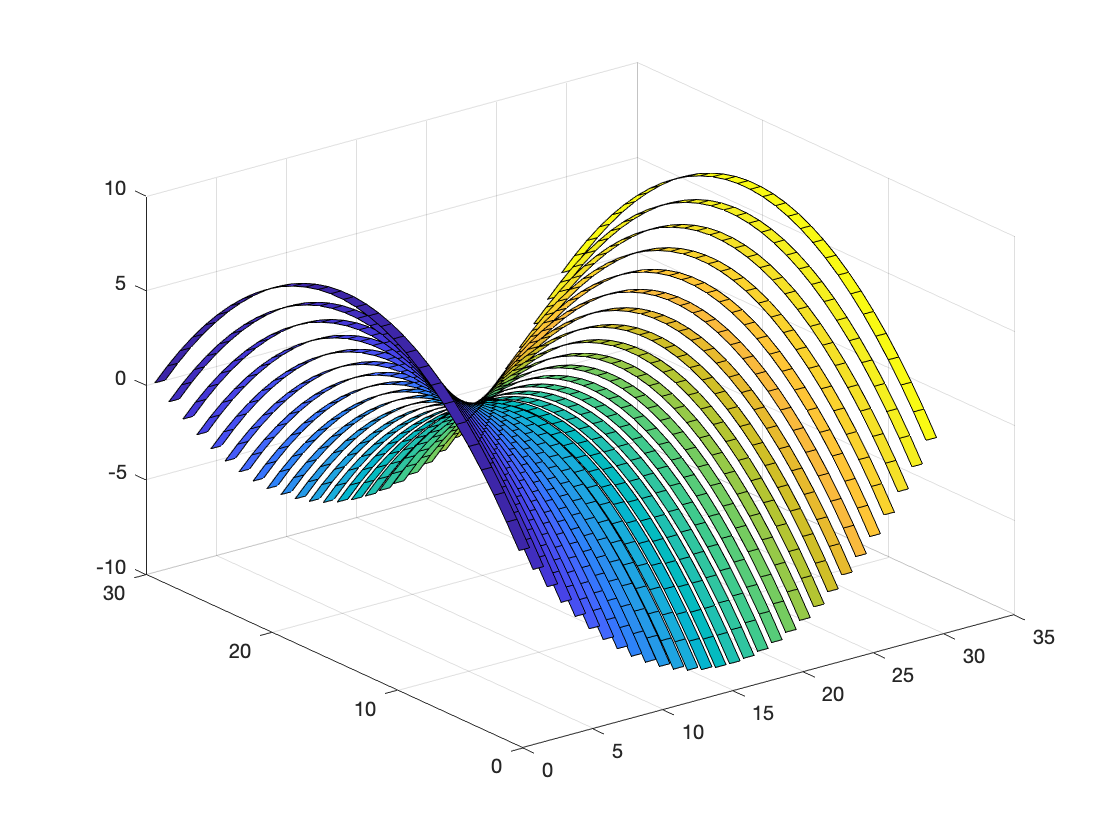

ribbon(z);

## **Customization**

### **Specify Ribbon Width and Specify X-Axis Ticks**

Use the third input to `ribbon` to specify the ribbon width. Use y-values as the first input to `ribbon` to use the actual y-coordinates on the y-axis. 

By default, the x-axis represents the ribbon number. To specify the actual x-coordinates, access the Axes object and specify the *XTickLabels* property.

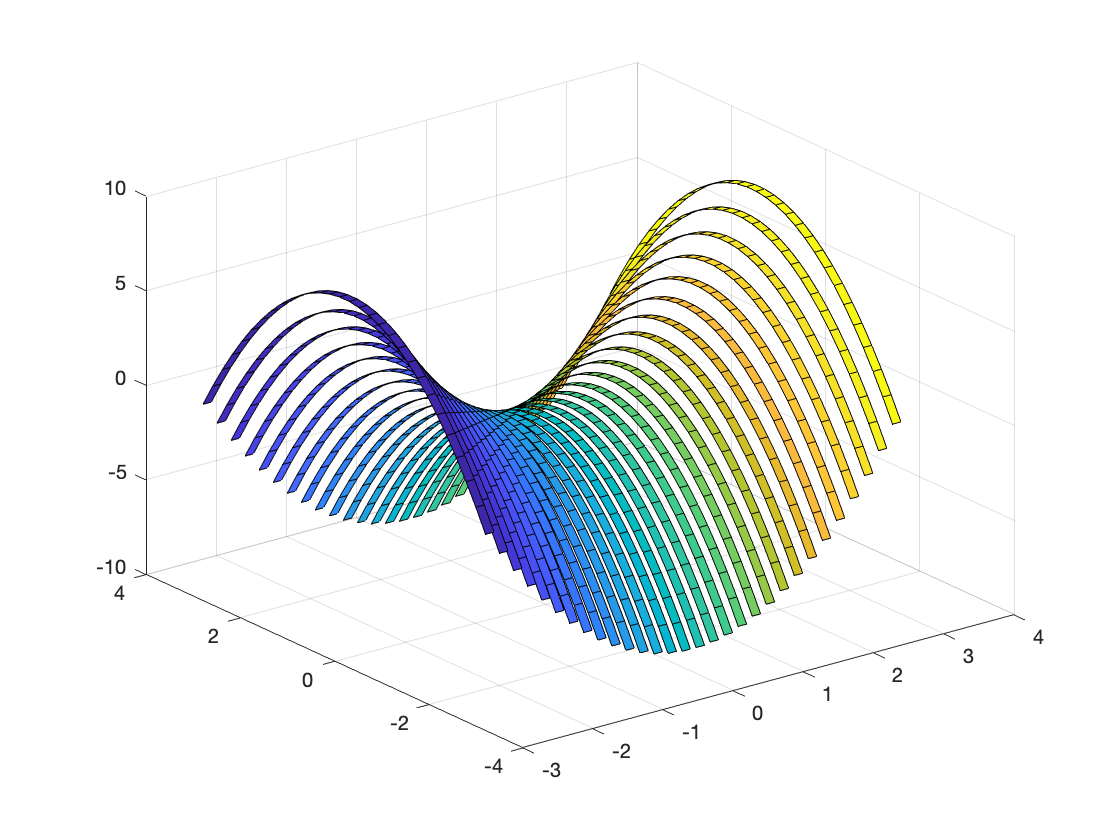

width = 0.6;

r = ribbon(y,z,...
    width);             % Specify the width as the third input to ribbon

ax = gca;               % Access the AXes object
ax.XTickLabels = -3:4;  % Specify the x-axis tick labels

### **Color Ribbons by Height **

By default, each ribbon has a different color. To color ribbons by their height along the z-axis, access the plot handle and set the *CData *and* FaceColor* properties. Set the *MeshStyle* property to *column* to remove the mesh lines cutting across each ribbon.

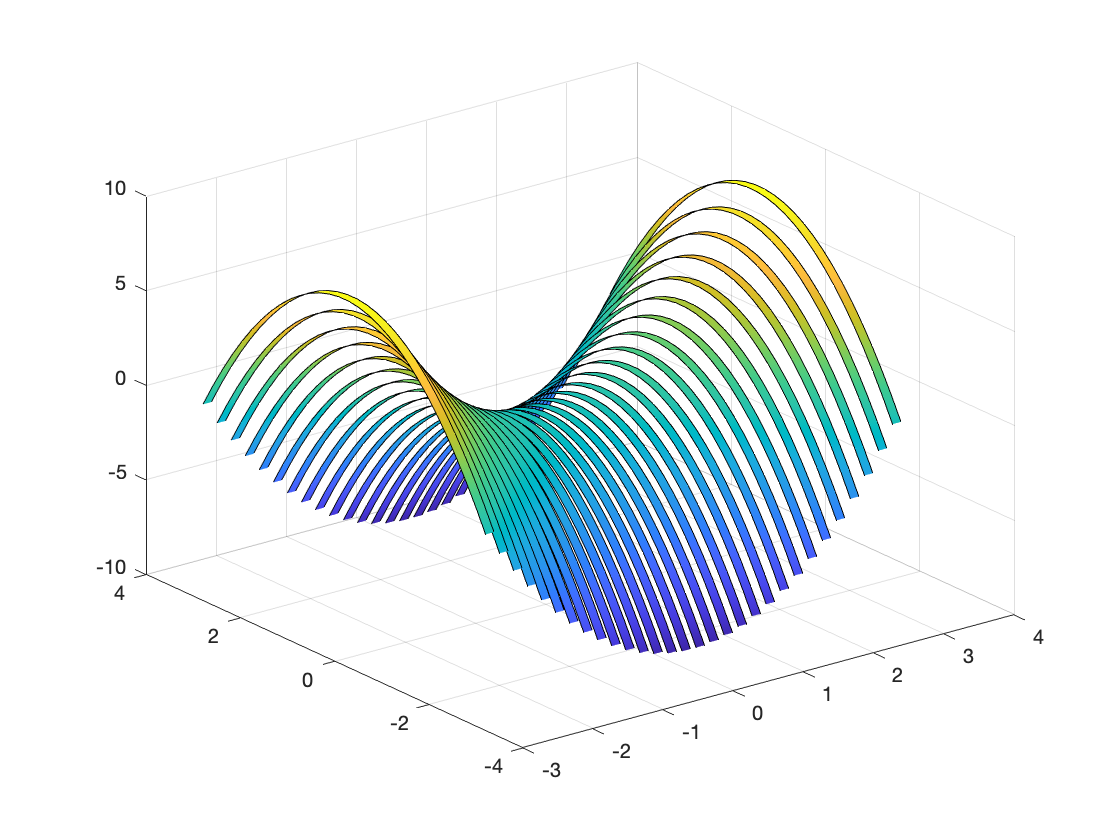

set(r, {'CData'}, get(r,"ZData"),...  % Specify the color data based on ZData
    "FaceColor","interp",...          % Specify the FaceColor property to 'interp' for smooth shading
    "MeshStyle","column");            % Specify the MeshStyle

### Change Chart Colormap

There are several default colormaps specified in MATLAB, some are shown in the drop down menu. Add axes labels and a title.

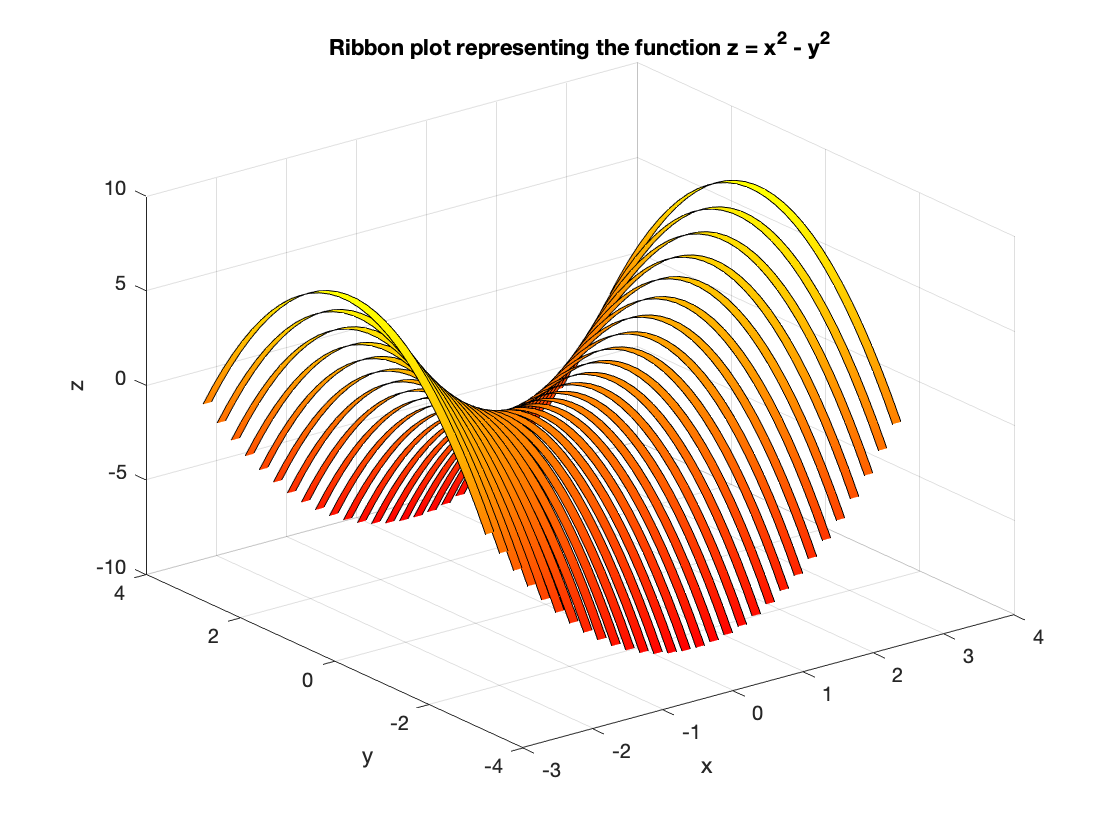

colormap("autumn");

xlabel("x");
ylabel("y");
zlabel("z");
title("Ribbon plot representing the function z = x^{2} - y^{2}")

## **Additional Information**

### **Get All Surface Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Surface, uncomment the following code. View or modify these properties using dot notation.

% get(r(1))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[ribbon](https://www.mathworks.com/help/matlab/ref/ribbon.html)

### Helper Functions

This function generates x, y and z data with the following relationship: $z=x^2 -y^2$.

function [x,y,z] = createData()
    [x,y] = peaks(30);
    z = (x.^2)-(y.^2);
end

Copyright (c) 2021, The MathWorks, Inc.